close all; clear all

# Example: Temperature sensor in a room.

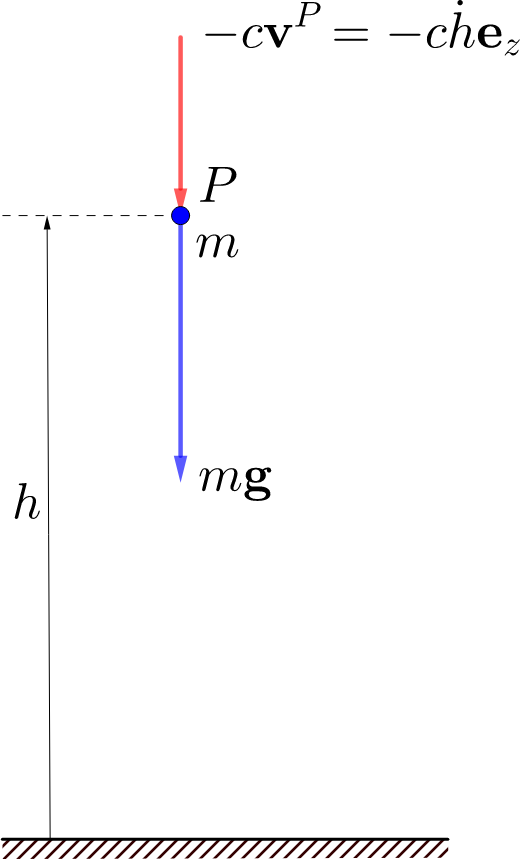

%Falling Particle in a visous medium.

# Solution:

## Parameter and initial state definition

global t t_0 t_end Delta_t
global sigma_u_actual sigma_z_actual seed
global z_actual_func u_actual_func
z_actual_func = @(t) actual_Vel_func(t);
u_actual_func = @(t) my_u_actual_func(t);
seed=12347; rng(seed); rng_status=rng;

Set initial time $t_0$, sampling frequency $\Delta t$ and final simulation time $t_{end}$

t_0=0;         		     %s
Delta_t=0.001;           %s
t_end=100;               %s

Define model parameters

global g_true v_lim
g_model= 9.8;            %m/s^2
g_true= 9.8;		     %m/s^2
v_lim=100;               %m/s

Initial state and variance $\mu_{x_0}$, $\sigma_{x_0}^2$, estimated from limits in historical meassurements

% Set mu_x_0 sigma2_x_0
mu_x_0=10;                  %m/s
sigma_x_0=20;               %m/s
Sigma2_x_0=sigma_x_0^2;     %(m/s)^2

Model equation error variance $\sigma^2_{u_{k}}$ and $\sigma^2_{w_k}$

% Set Sigma2_u
u=u_actual_func(t_0);
n_u=size(u,1);

sigma_u=zeros(size(u));
Sigma2_u=diag(sigma_u)^2;
sigma_u_actual=zeros(size(u));
Sigma2_u_actual=diag(sigma_u_actual)^2;

% Set Sigma2_w
%alpha=1;
alpha= g_model^2/v_lim; %ddx(0), max at t=0 -> approx g_model
% alpha= abs(-g_model/v_lim*(-g_model-g_model/v_lim*mu_x)); %ddx(t)
sigma_w_1=abs(g_true-g_model)*Delta_t;  %m/s
sigma_w_2=alpha/factorial(2) * Delta_t^2; %m/s
Sigma2_w=sigma_w_1^2 + sigma_w_2^2;     %(m/s)^2

Sensor equation error variance $\sigma^2_{z_{k+1}}$, $\sigma^2_{u_{k+1}}$ and $\sigma^2_{v_{k+1}}$

% Set sigma2_v
sigma_z_spec=1;           %m/s Value given by spec. sheet
sigma_z_actual=1;                %m/s Actual value
sigma_v=sigma_z_spec;     %m/s
Sigma2_v=sigma_v^2;       %(m/s)^2

Begin filtering

fid=fopen('sol.dat','w');

Read

rng(rng_status);
z=get_z();
u=get_u();

Write

fprintf(fid,'%.20e %.20e %.20e %.20e %.20e\n',t,mu_x,Sigma2_x,z,z_actual_func(t));

Filter iteration

% Iteration
for k=1:t_end/Delta_t

Model Equation State *Prediction* (estimation of state in k+1 form state and input in k)

$x_{k+1}=a~x_k+b~u_k+w_k$, model stochastic equation

$\hat{\mu}_{x_1}=a \hat{\mu}_{x_{k}}+b \hat{\mu}_{u_{k}}=\hat{\mu}_{x_{k+1}^{pred}}$, *Prediction estimation*, expected value of model stochastic equation

$I_{x_1}=1/\sigma_{x_1}^2=1/(a^2\sigma_{x_k}^2+b^2\sigma_{u_k}^2+\sigma_{w_k}^2)=1/{\hat{\sigma}^2_x}^{pred}=I_{x_{k+1}}^{pred}$, Information of *Prediction estimation, inverse of variance of Prediction estimation.*

Note that $b^2\sigma_{u_k}^2+\sigma_{w_k}^2$ is what in standard Kalman filtering literature is called "model covariance matrix" $Q$ (a escalar or $1\times1$ matrix in this example)

    % Model prediction (k+1 using model)
    mu_x_pred=mu_x+(-g_model/v_lim*mu_x-g_model)*Delta_t;
    Sigma2_x_pred=(1-g_model/v_lim*Delta_t)^2*Sigma2_x+Sigma2_w;
    I_x_pred=1/Sigma2_x_pred;

Read

    % read (take measurement)
    t=k*Delta_t;
    z=get_z();
    u=get_u();

Sensor Equation State *Observation* (estimation of state in k+1 from sensor and input in k+1)

$z_{k+1}=c~x_{k+1}+d~u_{k+1}+v_{k+1} \Rightarrow  x_{k+1}=\frac{1}{c}(z_{k+1}-(d~u_{k+1}+v_{k+1}))$, sensor stochastic equation ordered to render state

$\hat{\mu}_{x_2}=\frac{1}{c} (\hat{\mu}_{z_{k+1}}+b \hat{\mu}_{u_{k+1}})=\hat{\mu}_{x_{k+1}^{obs}}$, Observation* estimation*, expected value of model stochastic equation

$I_{x2}=1/\sigma_{x_2}^2=1/(\frac{\sigma_{z_{k+1}}^2}{c^2}+\frac{d^2~\sigma_{u_{k+1}}^2}{c^2}+\frac{\sigma_{v_{k+1}}^2}{c^2})=\frac{c^2}{   {\sigma_{z_{k+1}}^2}+{d^2~\sigma_{u_{k+1}}^2}+\sigma_{v_{k+1}}^2   }=I_{x_{k+1}}^{obs}$, Information of *Observation estimation, inverse of variance of Observation estimation.*

Note that ${\sigma_{z_{k+1}}^2}+{d^2~\sigma_{u_{k+1}}^2}+\sigma_{v_{k+1}}^2}$ is what in standard Kalman filtering literature is called "sensor covariance matrix" $R$ (a escalar or $1\times1$ matrix in this example)

    % Sensor prediction (k+1 using sensor)
    mu_x_obs=z;
    Sigma2_x_obs=Sigma2_v;
    I_x_obs=1/Sigma2_x_obs;

Correction


$$\hat{\mu}_{x_{k+1}}=\frac{{I_{x_{k+1}}^{pred}}{\hat{\mu}_{x_{k+1}^{pred}}}+{I_{x_{k+1}}^{obs}}{\hat{\mu}_{x_{k+1}^{obs}}}}{{I_{x_{k+1}}}}$$



$$I_{x_{k+1}}=I_{x_{k+1}}^{pred}+I_{x_{k+1}}^{obs} \Rightarrow \sigma_{\hat{\mu}_{x_{k+1}}}^2=\frac{1}{I_{x_{k+1}}}$$


    % Correction
    I_total=I_x_pred+I_x_obs;
    mu_x=(mu_x_pred*I_x_pred+mu_x_obs*I_x_obs)/I_total;
    Sigma2_x=1/I_total;

Write

    fprintf(fid,'%.20e %.20e %.20e %.20e %.20e\n',t,mu_x,Sigma2_x,z,z_actual_func(t));

end

End filtering

fclose(fid);

## Plotting

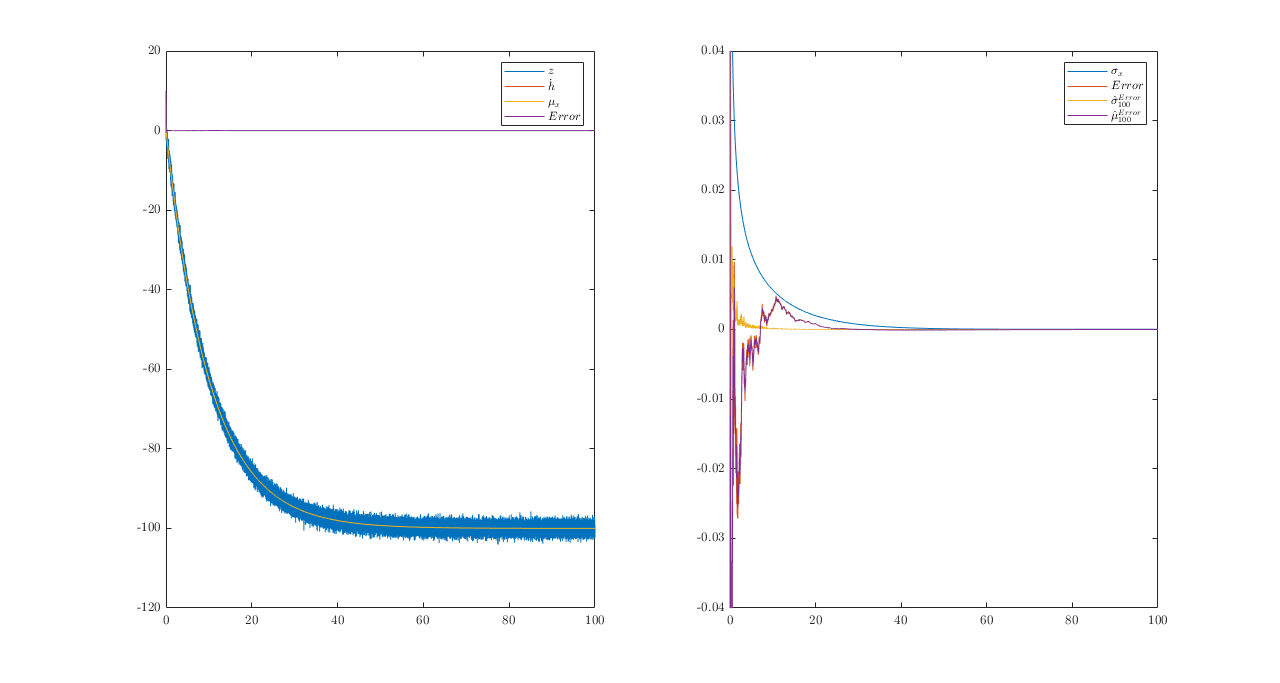

load -ascii sol.dat
t=sol(:,1);
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
figure('units','normalized','outerposition',[0 0 0.5 0.5]);
h(1)=subplot(1,2,1);
plot(t,sol(:,4),t,sol(:,5),t,sol(:,2),t,sol(:,2)-sol(:,5))
I=legend('$z$','$\dot{h}$','$\mu_x$', '$Error$');
set(I,'interpreter','latex');
h(2)=subplot(1,2,2);
n_window=100;
plot(t,sol(:,3).^0.5,t,sol(:,2)-sol(:,5),t,ones(size(t)).*movstd(sol(:,2)-sol(:,5),n_window),t,ones(size(t)).*movmean(sol(:,2)-sol(:,5),n_window))
ylim([-0.04,0.04])
I=legend('$\sigma_x$', '$Error$', ['$\hat{\sigma}^{Error}_{',num2str(n_window),'}$'],['$\hat{\mu}^{Error}_{',num2str(n_window),'}$']);
set(I,'interpreter','latex');

saveas(gcf,'Particle_falling_in_a_viscous_medium.png')

## Functions to define sensor and input meassurement

The following function simulates the "actual" value of the variable meassured by the sensor

function z_actual=actual_Vel_func(t)
global g_true v_lim
z_actual=-(g_true - g_true*exp(-g_true/v_lim*t))/(g_true/v_lim);
end

The following function simulates meassurement adding noise to the "actual" value of the variable meassured by the sensor

function z_meas=get_z()
global t sigma_z_actual
global z_actual_func
z_actual=z_actual_func(t);
z_meas=z_actual+randn*sigma_z_actual;
end

The following function simulates the "actual" input to the system

function u_actual=my_u_actual_func(t)
u_actual=zeros(0,1);
end

The following function simulates input meassurement adding noise to the "actual" input to the system

function u_meas=get_u()
global t sigma_u_actual
global u_actual_func
u_actual=u_actual_func(t);
u_meas=u_actual+sigma_u_actual.*randn(size(u_actual));
end